clc; clear all; close all;

s=tf('s');
gp = 1.75*(-3*s+1)*(-5*s+1)*exp(-1.25*s)/((10*s+1)*(4*s+1)^2)

gp =
 
                   26.25 s^2 - 14 s + 1.75
  exp(-1.25*s) * ---------------------------
                 160 s^3 + 96 s^2 + 18 s + 1
 
Continuous-time transfer function.
Model Properties


INV = (3*s+1)*(5*s+1)\((10*s+1)*(4*s+1)^2)

INV =
 
  160 s^3 + 96 s^2 + 18 s + 1
  ---------------------------
       15 s^2 + 8 s + 1
 
Continuous-time transfer function.
Model Properties


INV = INV/(dcgain(INV)*dcgain(gp));


## Gamma = 0

Lambda = 1

Lambda = 1

F = 1/(Lambda*s+1)^1 % n >= 0 + deg(INV) = 0+1 =1

F =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


C = INV*F

C =
 
       160 s^3 + 96 s^2 + 18 s + 1
  --------------------------------------
  26.25 s^3 + 40.25 s^2 + 15.75 s + 1.75
 
Continuous-time transfer function.
Model Properties


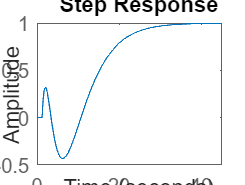

step(gp*C); hold on

## Gamma != 0

Lambda2 = 1;

Lambda2 = 1

gamma2 = 0.01;

gamma2 = 0.1000

F = (gamma2*s+1)/(Lambda2*s+1)^2 % n >= 1 + deg(INV) = 0+1 =1

F =
 
    0.1 s + 1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


C = INV*F

C =
 
   16 s^4 + 169.6 s^3 + 97.8 s^2 + 18.1 s + 1
  ---------------------------------------------
  26.25 s^4 + 66.5 s^3 + 56 s^2 + 17.5 s + 1.75
 
Continuous-time transfer function.
Model Properties


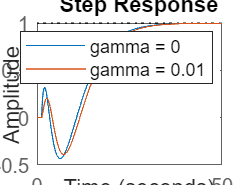

step(gp*C)
legend('gamma = 0','gamma = 0.01')